% (2*x*y*exp(x^2)+log(y))*dx+(exp(x^2)+x/y)*dy=0
% y(0)=1

% 1)
clear
% y'=-(2*x*y*exp(x^2)+log(y))/(exp(x^2)+x/y)
syms x y(x)
eqn=(2*x*y*exp(x^2)+log(y))+(exp(x^2)+x/y)*diff(y)

$$eqn(x) = \left({\mathrm{e}}^{x^{2}}+\frac{x}{y\left(x\right)}\right)\,\frac{\partial }{\partial x}y\left(x\right)+\log\left(y\left(x\right)\right)+2\,x\,{\mathrm{e}}^{x^{2}}\,y\left(x\right)$$

cond=y(0)==1

$$cond = y\left(0\right)=1$$

ySol=dsolve(eqn,cond)

 
ySol =
 
[ empty sym ]
 


% [ empty sym ]

% 2)
syms x y dx dy C
eq1=(2*x*y*exp(x^2)+log(y))*dx+(exp(x^2)+x/y)*dy

$$eq1 = \mathrm{dy}\,\left({\mathrm{e}}^{x^{2}}+\frac{x}{y}\right)+\mathrm{dx}\,\left(\log\left(y\right)+2\,x\,y\,{\mathrm{e}}^{x^{2}}\right)$$

cfs=coeffs(eq1,[dy dx])

$$cfs = \left(\begin{array}{cc} \log\left(y\right)+2\,x\,y\,{\mathrm{e}}^{x^{2}} & {\mathrm{e}}^{x^{2}}+\frac{x}{y} \end{array}\right)$$

P=cfs(1), Q=cfs(2)

$$P = \log\left(y\right)+2\,x\,y\,{\mathrm{e}}^{x^{2}}$$

$$Q = {\mathrm{e}}^{x^{2}}+\frac{x}{y}$$

f=simplify(diff(P,y)-diff(Q,x))

$$f = 0$$

% dPy==dQx

% U(x,y)
% dUx=P, dUy=Q
syms C(y)
U=int(P,x)+C(y)

$$U = C\left(y\right)+y\,{\mathrm{e}}^{x^{2}}+x\,\log\left(y\right)$$

% C(y) + y*exp(x^2) + x*log(y)
dUy=diff(U,y)

$$dUy = {\mathrm{e}}^{x^{2}}+\frac{\partial }{\partial y}C\left(y\right)+\frac{x}{y}$$

% exp(x^2) + diff(C(y), y) + x/y
dCy=simplify(dUy-Q)

$$dCy = \frac{\partial }{\partial y}C\left(y\right)$$

% dCy=0
syms C1
U=y*exp(x^2) + x*log(y)+ C1

$$U = C_{1}+y\,{\mathrm{e}}^{x^{2}}+x\,\log\left(y\right)$$

U1=subs(U,[x y],[0 1])

$$U1 = C_{1}+1$$

% C1=-1
% y*exp(x^2) + x*log(y) = 1
U1=y*exp(x^2) + x*log(y) - 1

$$U1 = y\,{\mathrm{e}}^{x^{2}}+x\,\log\left(y\right)-1$$

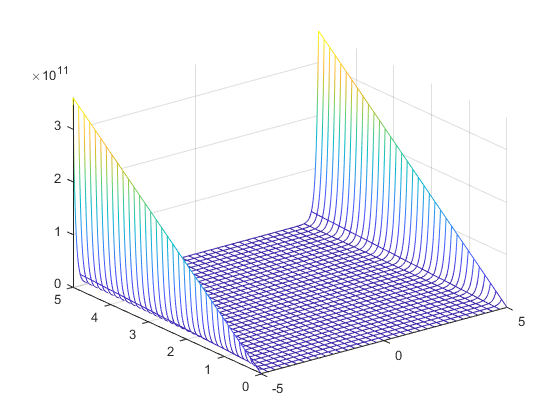

fmesh(U1)

% 3)
x0=0;y0=0;
U=simplify(int(P,x,x0,x)+int(subs(Q,x,x0),y,y0,y))

$$U = y\,{\mathrm{e}}^{x^{2}}+x\,\log\left(y\right)$$

syms C
eq2=U==C

$$eq2 = y\,{\mathrm{e}}^{x^{2}}+x\,\log\left(y\right)=C$$

C1=solve(subs(eq2,[x y],[0 1]),C)

$$C1 = 1$$

eq3=subs(eq2,C,C1)

$$eq3 = y\,{\mathrm{e}}^{x^{2}}+x\,\log\left(y\right)=1$$